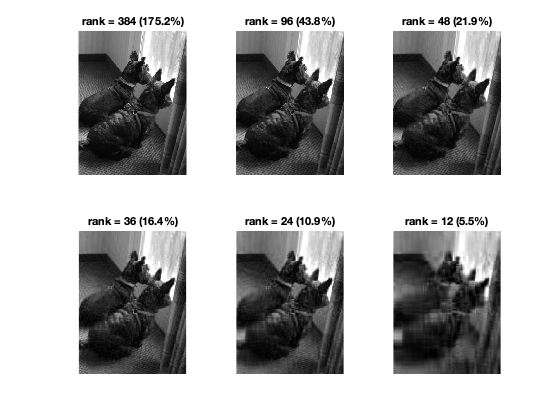

% Read a JPG image into memory.
I = imread('scotties.jpg');
% The original image was in color (RGB).
% Make it a grayscale image instead.
X = rgb2gray(I);
% For this example, let's reduce the image
% size by a factor of four.
X = imresize(X, 0.25);
% Grayscale images are by default an integer
% between 0-255 (uint8). Make them a real
% number (double precision float) instead.
X = im2double(X);

[U,S,V] = svd(X);

% Find the original image size and specify
% the ranks for downsampling.
% The original image has rank = 384.
[m,n] = size(X);
ranks = [384 96 48 36 24 12];
for i = 1:length(ranks)
    % Approximate the image using rank k.
    k = ranks(i);
    C = U(:,1:k) * S(1:k,1:k) * V(:,1:k)';
    % Show the image, the rank, and the memory used as
    % the percent of the original mxn matrix.
    subplot(2,3,i)
    imshow(C)
    title(sprintf('rank = %i (%0.1f%%)',k, k*(m+n+1)/(m*n)*100))
end

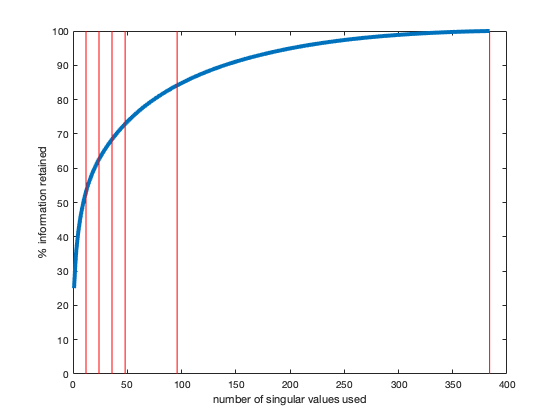

% Plot the cumulative distribution of the singular values.
figure()
plot(cumsum(diag(S))/sum(diag(S))*100,'LineWidth',4)
xlabel('number of singular values used')
ylabel('% information retained')

% Draw vertical lines for each of the ranks sampled above.
hold on
for r = ranks
    plot([r r],[0 100],'r')
end
hold off

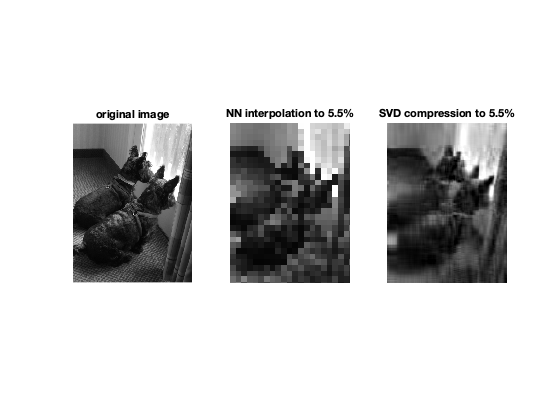

% Comparing SVD compression to nearest-neighbor (NN) interpolation

% Plot the original image.
subplot(1,3,1)
imshow(X);
title('original image')

% Plot the interpolated image
subplot(1,3,2)
% We first downsample the image to 5.5%, then rescale it back to the
% original size for plotting.
Xnn = imresize(imresize(X,0.055,'nearest'), 1/0.055, 'nearest', 'OutputSize', size(X));
imshow(Xnn)
title('NN interpolation to 5.5%')

% Plot the SVD-compressed image (rank=12, 5.5%)
subplot(1,3,3)
imshow(C)
title('SVD compression to 5.5%')